# Pré-codificação

### ZF

Calcula W = Hᴴ (H Hᴴ)⁻¹, a matriz que anula a interferência entre streams

function W = zf_precoder(H)
W = H' / (H*H');
end

### SVD

SVD do canal completo: limite superior (receptores a cooperar)

function [W, G, s] = svd_precoder(H)
[U, S, V] = svd(H);
W = V;
G = U';
s = diag(S);
end

### Water-filling

Distribui a potência pelos canais para maximizar a capacidade

function p = water_filling(g, P)
% g: ganhos de potencia dos canais (sigma_i^2); P: potencia total (ruido unitario)
g = g(:);  n = numel(g);
[gs, ordem] = sort(g, 'descend');
inv_g = 1 ./ gs;
mu = (P + cumsum(inv_g)) ./ (1:n)';       % nivel de agua candidato com k canais
k  = find(mu > inv_g, 1, 'last');         % nº de canais activos
p = zeros(n,1);
p(ordem) = max(mu(k) - inv_g, 0);
end

### BD

Block Diagonalization: anula a interferência entre utilizadores, mas deixa a dos streams do mesmo user (que ele resolve com as suas antenas)

function [W, G, e] = bd_precoder(H, sizes)
% Block Diagonalization: W_j = V0_j * V1_j
%   V0_j : base do espaco nulo dos canais dos outros utilizadores
%   V1_j : SVD do canal efectivo H_j*V0_j
[Nrt, Nt] = size(H);
st = [0 cumsum(sizes)];
quadrada = (Nrt == Nt);
if quadrada, Hi = inv(H); end         % atalho: colunas de inv(H) geram o espaco nulo
W = [];  G = zeros(Nrt, Nrt);  e = [];  r = 0;
for j = 1:numel(sizes)
    a = st(j)+1;  b = st(j+1);
    Hj = H(a:b, :);                       % canal do user j
    if quadrada
        [V0, ~] = qr(Hi(:, a:b), 0);      % Hi(:,a:b) e ortogonal as linhas dos outros users
    else
        Ht = H([1:a-1, b+1:Nrt], :);      % canal dos outros users
        [~, ~, V] = svd(Ht);
        V0 = V(:, min(size(Ht))+1:end);   % espaco nulo de Ht
    end
    [U, S, V1] = svd(Hj*V0, 'econ');      % canal efectivo do user j
    s = diag(S);  L = numel(s);
    W = [W, V0*V1];                       %#ok<AGROW>
    e = [e; s];                           %#ok<AGROW>
    G(r+1:r+L, a:b) = U';
    r = r + L;
end
G = G(1:r, :);
end

### Modulação

function [u, bits] = mod_qam(Ns, T, M)
% Simbolos QAM Gray, potencia media 1 (M = 4: QPSK, M = 16: 16-QAM)
if M == 4
    bits = {randi([0 1],Ns,T), randi([0 1],Ns,T)};            % sinal de I e de Q
    u = ((1-2*bits{1}) + 1j*(1-2*bits{2})) / sqrt(2);
else
    bits = {randi([0 1],Ns,T), randi([0 1],Ns,T), randi([0 1],Ns,T), randi([0 1],Ns,T)};
    u = ((1-2*bits{1}).*(3-2*bits{3}) + 1j*(1-2*bits{2}).*(3-2*bits{4})) / sqrt(10);
end
end

function ne = conta_erros(uh, bits, M)
ne = sum(sum((real(uh) < 0) ~= bits{1})) + sum(sum((imag(uh) < 0) ~= bits{2}));
if M == 16
    ne = ne + sum(sum((abs(real(uh))*sqrt(10) < 2) ~= bits{3})) ...
            + sum(sum((abs(imag(uh))*sqrt(10) < 2) ~= bits{4}));
end
end

function p = ber_teo(g, M)
% BER teorica (AWGN, Gray) para SNR por simbolo g (potencia media 1)
if M == 4
    p = 0.5*erfc(sqrt(g/2));
else
    a = sqrt(g/10);
    p = 3/8*erfc(a) + 1/4*erfc(3*a) - 1/8*erfc(5*a);
end
end

function R = simula_cenario(Nt, sizes, D, T, snr_db, M)
% D realizacoes de canal Rayleigh; devolve BER (sim. e teorica), capacidade e EVM
Nrt = sum(sizes);  Ns = Nrt;  nS = numel(snr_db);
erros = zeros(nS,3);  teo = zeros(nS,3);  cap = zeros(nS,5);
EVMd  = zeros(D,nS,3);                                   % colunas: ZF, SVD, BD
for d = 1:D
    H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    W_zf = zf_precoder(H);
    [W_svd, G_svd, s]  = svd_precoder(H);
    [W_bd, G_bd, e_bd] = bd_precoder(H, sizes);
    [u, bits] = mod_qam(Ns, T, M);
    for i = 1:nS
        snr_i = 10^(snr_db(i)/10);
        n     = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2 = Ns*snr_i / norm(W_zf,'fro')^2;
        Y = cell(1,3);
        Y{1} = (H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2);
        Y{2} = (G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s);
        Y{3} = (G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd);
        for k = 1:3
            erros(i,k)  = erros(i,k) + conta_erros(Y{k}, bits, M);
            EVMd(d,i,k) = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
        end
        teo(i,1) = teo(i,1) + ber_teo(beta2, M);
        teo(i,2) = teo(i,2) + mean(ber_teo(snr_i*s.^2, M));
        teo(i,3) = teo(i,3) + mean(ber_teo(snr_i*e_bd.^2, M));
        p_s = water_filling(s.^2,    Ns*snr_i);
        p_b = water_filling(e_bd.^2, numel(e_bd)*snr_i);
        cap(i,1) = cap(i,1) + Ns*log2(1 + beta2);
        cap(i,2) = cap(i,2) + sum(log2(1 + snr_i*s.^2));
        cap(i,3) = cap(i,3) + sum(log2(1 + p_s.*s.^2));
        cap(i,4) = cap(i,4) + sum(log2(1 + snr_i*e_bd.^2));
        cap(i,5) = cap(i,5) + sum(log2(1 + p_b.*e_bd.^2));
    end
end
R.BER     = erros / (log2(M)*Ns*T*D);
R.BER(R.BER == 0) = NaN;
R.BER_teo = teo / D;
R.C       = cap / D;
R.EVM     = EVMd;
end

function plota_cenario(R4, R16, snr_db, nome)
D = size(R4.EVM, 1);
figure('Name', nome, 'Position', [100 100 1100 600]);
subplot(2,3,1); semilogy(snr_db, R4.BER, 'o-', 'LineWidth', 1.2); grid on; ylim([1e-6 1]);
legend('ZF','SVD','BD'); xlabel('SNR por stream [dB]'); ylabel('BER'); title('BER, QPSK');
subplot(2,3,2); semilogy(snr_db, R16.BER, 'o-', 'LineWidth', 1.2); grid on; ylim([1e-6 1]);
xlabel('SNR por stream [dB]'); ylabel('BER'); title('BER, 16-QAM');
subplot(2,3,3); plot(snr_db, R4.C, 'o-', 'LineWidth', 1.2); grid on;
legend('ZF','SVD','SVD wf','BD','BD wf','Location','northwest');
xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]'); title('Capacidade media');
subplot(2,3,4); semilogy(snr_db, squeeze(median(R4.EVM,1)), 'o-', 'LineWidth', 1.2); hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--'); grid on;
xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]'); title('EVM, QPSK (limite 5G 17.5%)');
subplot(2,3,5); semilogy(snr_db, squeeze(median(R16.EVM,1)), 'o-', 'LineWidth', 1.2); hold on;
plot(snr_db, 12.5*ones(size(snr_db)), 'k--'); grid on;
xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]'); title('EVM, 16-QAM (limite 5G 12.5%)');
subplot(2,3,6); plot(snr_db, mean(R4.EVM(:,:,1) < 17.5, 1), 'o-', ...
                     snr_db, mean(R16.EVM(:,:,1) < 12.5, 1), 's-', 'LineWidth', 1.2); grid on;
legend('QPSK (17.5%)','16-QAM (12.5%)','Location','northwest'); xlabel('SNR por stream [dB]');
ylabel('Fraccao de canais que cumprem'); title('Canais que cumprem o EVM do 5G');
if exist('sgtitle', 'file'), sgtitle(sprintf('%s (%d realizacoes)', nome, D)); end
end

# **Fase 1**

**Comum a todos os cenários**

quick = false;
rng('default');        % repoe o gerador moderno (o tests_phase1 usa o antigo)
snr_db = 0:2:40;
if quick, D12 = 50;   D512 = 3;
else,     D12 = 2000; D512 = 200; end
T12 = 50;  T512 = 10;

# Cenários

### Cenário 1 A

16 users × 1 antena

Nt = 16;  sizes = ones(1,16);          % 16 users x 1 antena
Nrt = sum(sizes);                      % total de antenas receptoras
rng(1);
H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);   % canal Rayleigh

W_zf = zf_precoder(H);
[W_svd, G_svd, s] = svd_precoder(H);

% verificacao: interferencia entre streams anulada
fprintf('ZF : ||H*W - I||        = %.2e\n', norm(H*W_zf - eye(Nrt)));

ZF : ||H*W - I||        = 5.90e-13


fprintf('SVD: ||G*H*W - diag(s)|| = %.2e\n', norm(G_svd*H*W_svd - diag(s)));

SVD: ||G*H*W - diag(s)|| = 1.30e-14


snr_dB = 20;  snr = 10^(snr_dB/10);
Ns = Nrt;  PT = Ns*snr;

beta2 = PT / norm(W_zf,'fro')^2;
C_zf  = Ns*log2(1 + beta2);
C_svd = sum(log2(1 + snr*s.^2));

fprintf('Capacidade ZF  : %.1f bit/s/Hz\n', C_zf);

Capacidade ZF  : 53.7 bit/s/Hz


fprintf('Capacidade SVD : %.1f bit/s/Hz\n', C_svd);

Capacidade SVD : 148.4 bit/s/Hz


p_wf  = water_filling(s.^2, PT);
C_wf  = sum(log2(1 + p_wf.*s.^2));
fprintf('Capacidade SVD (water-filling): %.1f bit/s/Hz\n', C_wf);

Capacidade SVD (water-filling): 149.2 bit/s/Hz


fprintf('Streams activos: %d de %d\n', sum(p_wf > 0), Ns);

Streams activos: 15 de 16


[W_bd, G_bd, e_bd] = bd_precoder(H, sizes);
Ns_bd = numel(e_bd);

fprintf('BD: ||G*H*W - diag(e)||  = %.2e\n', norm(G_bd*H*W_bd - diag(e_bd)));

BD: ||G*H*W - diag(e)||  = 9.34e-15



C_bd_eq = sum(log2(1 + snr*e_bd.^2));                       % potencia igual
p_bd    = water_filling(e_bd.^2, Ns_bd*snr);
C_bd_wf = sum(log2(1 + p_bd.*e_bd.^2));                     % water-filling
fprintf('Capacidade BD: eq %.1f | wf %.1f bit/s/Hz\n', C_bd_eq, C_bd_wf);

Capacidade BD: eq 71.0 | wf 71.1 bit/s/Hz


T  = 1000;                                          % simbolos por stream
b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);            % QPSK, potencia media 1
n  = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);    % ruido, variancia 1

% --- ZF
x     = sqrt(beta2) * W_zf * u;
y     = H*x + n;
u_hat = y / sqrt(beta2);
errs  = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_zf = errs / (2*Ns*T);
EVM_zf = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_zf_teo = 0.5*erfc(sqrt(beta2/2));               % teoria (todos os streams com SNR = beta2)

% --- SVD, potencia igual por stream
xs     = W_svd * (sqrt(snr)*u);
ys     = G_svd * (H*xs + n);
u_hat  = ys ./ (sqrt(snr)*s);
errs   = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_svd = errs / (2*Ns*T);
EVM_svd = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_svd_teo = mean(0.5*erfc(sqrt(snr*s.^2/2)));

fprintf('ZF : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_zf, BER_zf_teo, EVM_zf);

ZF : BER 1.34e-03 (teoria 1.18e-03) | EVM 32.9 %


fprintf('SVD: BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_svd, BER_svd_teo, EVM_svd);

SVD: BER 1.34e-02 (teoria 1.38e-02) | EVM 32.9 %


% --- BD, potencia igual por stream
xb     = W_bd * (sqrt(snr)*u);
ub_hat = (G_bd * (H*xb + n)) ./ (sqrt(snr)*e_bd);
errs   = sum(sum((real(ub_hat) < 0) ~= b1)) + sum(sum((imag(ub_hat) < 0) ~= b2));
BER_bd = errs / (2*Ns*T);
EVM_bd = 100*sqrt(mean(abs(ub_hat(:) - u(:)).^2));
BER_bd_teo = mean(0.5*erfc(sqrt(snr*e_bd.^2/2)));
fprintf('BD : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_bd, BER_bd_teo, EVM_bd);

BD : BER 7.31e-03 (teoria 7.62e-03) | EVM 32.9 %



D = D12;  T = T12;                                    % realizacoes e simbolos por stream (secção Comum)
erros = zeros(numel(snr_db), 3);                      % colunas: ZF, SVD, BD
cap = zeros(numel(snr_db), 5);     % ZF | SVD eq | SVD wf | BD eq | BD wf
teo = zeros(numel(snr_db), 3);
EVMd = zeros(D, numel(snr_db), 3);

for d = 1:D
    H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    W_zf = zf_precoder(H);
    [W_svd, G_svd, s]   = svd_precoder(H);
    [W_bd, G_bd, e_bd]  = bd_precoder(H, sizes);

    b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
    u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);
    cnt = @(uh) sum(sum((real(uh) < 0) ~= b1)) + sum(sum((imag(uh) < 0) ~= b2));

    for i = 1:numel(snr_db)
        snr_i = 10^(snr_db(i)/10);
        n     = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2 = Ns*snr_i / norm(W_zf,'fro')^2;
        erros(i,1) = erros(i,1) + cnt((H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2));
        erros(i,2) = erros(i,2) + cnt((G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s));
        erros(i,3) = erros(i,3) + cnt((G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd));
        teo(i,1) = teo(i,1) + 0.5*erfc(sqrt(beta2/2));
        teo(i,2) = teo(i,2) + mean(0.5*erfc(sqrt(snr_i*s.^2/2)));
        teo(i,3) = teo(i,3) + mean(0.5*erfc(sqrt(snr_i*e_bd.^2/2)));
        p_s = water_filling(s.^2,    Ns*snr_i);
        p_b = water_filling(e_bd.^2, numel(e_bd)*snr_i);
        cap(i,1) = cap(i,1) + Ns*log2(1 + beta2);
        cap(i,2) = cap(i,2) + sum(log2(1 + snr_i*s.^2));
        cap(i,3) = cap(i,3) + sum(log2(1 + p_s.*s.^2));
        cap(i,4) = cap(i,4) + sum(log2(1 + snr_i*e_bd.^2));
        cap(i,5) = cap(i,5) + sum(log2(1 + p_b.*e_bd.^2));
        Y = cell(1,3);
        Y{1} = (H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2);
        Y{2} = (G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s);
        Y{3} = (G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd);
        for k = 1:3
            erros(i,k)   = erros(i,k) + cnt(Y{k});
            EVMd(d,i,k)  = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
        end
    end
end
BER = erros / (D*2*Ns*T);
BER(BER == 0) = NaN;
BER_teo = teo / D;
idx = ismember(snr_db, [20 30 40]);
disp([snr_db(idx)' BER(idx,:) BER_teo(idx,:)])      % SNR | sim ZF SVD BD | teoria ZF SVD BD

   20.0000    0.0138    0.0084    0.0132    0.0068    0.0042    0.0066
   30.0000    0.0031    0.0013    0.0027    0.0016    0.0006    0.0014
   40.0000    0.0005    0.0003    0.0005    0.0003    0.0001    0.0002



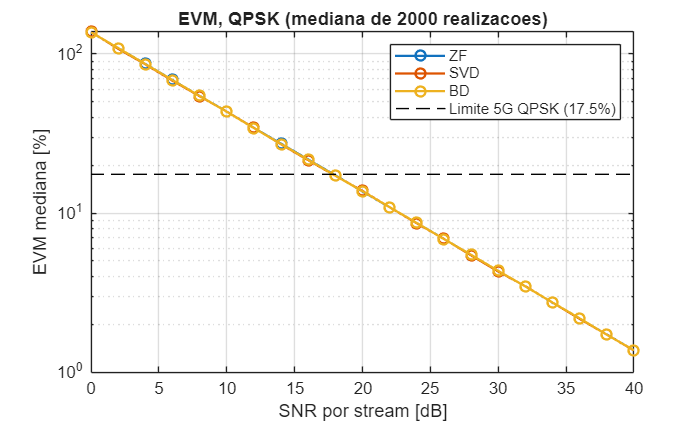

C = cap / D;
figure; plot(snr_db, C, 'o-', 'LineWidth', 1.4); grid on;
legend('ZF', 'SVD', 'SVD (water-filling)', 'BD', 'BD (water-filling)', 'Location', 'northwest');
xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]');
title(sprintf('Capacidade media (%d realizacoes)', D));
EVM_med  = squeeze(median(EVMd, 1));        % mediana sobre canais (n_snr x 3)
EVM_frac = squeeze(mean(EVMd < 17.5, 1));   % fraccao de canais abaixo do limite QPSK
figure; semilogy(snr_db, EVM_med, 'o-', 'LineWidth', 1.4); grid on; hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--');
legend('ZF', 'SVD', 'BD', 'Limite 5G QPSK (17.5%)'); xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]');
title(sprintf('EVM, QPSK (mediana de %d realizacoes)', D));

i3 = ismember(snr_db, [15 20 30]);
disp([snr_db(i3)' EVM_med(i3,:) EVM_frac(i3,:)])    % SNR | mediana ZF SVD BD | fraccao ZF SVD BD

   20.0000   13.6524   13.7635   13.6932    0.6875    0.6890    0.6870
   30.0000    4.3204    4.2885    4.3267    0.9600    0.9590    0.9595



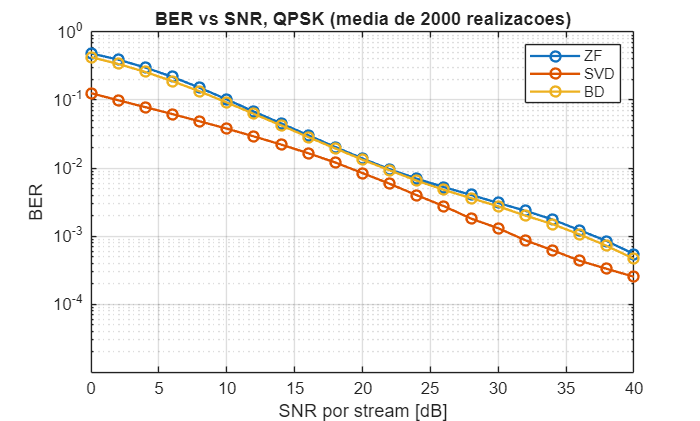



figure; semilogy(snr_db, BER, 'o-', 'LineWidth', 1.4); grid on; ylim([1e-5 1]);
legend('ZF', 'SVD', 'BD'); xlabel('SNR por stream [dB]'); ylabel('BER');
title(sprintf('BER vs SNR, QPSK (media de %d realizacoes)', D));

### Cenário 1 B

2 users × 8 antenas

Nt = 16;  sizes = [8 8];               % 2 users x 8 antena
Nrt = sum(sizes);                      % total de antenas receptoras
rng(1);
H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);   % canal Rayleigh

W_zf = zf_precoder(H);
[W_svd, G_svd, s] = svd_precoder(H);

% verificacao: interferencia entre streams anulada
fprintf('ZF : ||H*W - I||        = %.2e\n', norm(H*W_zf - eye(Nrt)));

ZF : ||H*W - I||        = 5.90e-13


fprintf('SVD: ||G*H*W - diag(s)|| = %.2e\n', norm(G_svd*H*W_svd - diag(s)));

SVD: ||G*H*W - diag(s)|| = 1.30e-14


snr_dB = 20;  snr = 10^(snr_dB/10);
Ns = Nrt;  PT = Ns*snr;

beta2 = PT / norm(W_zf,'fro')^2;
C_zf  = Ns*log2(1 + beta2);
C_svd = sum(log2(1 + snr*s.^2));

fprintf('Capacidade ZF  : %.1f bit/s/Hz\n', C_zf);

Capacidade ZF  : 53.7 bit/s/Hz


fprintf('Capacidade SVD : %.1f bit/s/Hz\n', C_svd);

Capacidade SVD : 148.4 bit/s/Hz


p_wf  = water_filling(s.^2, PT);
C_wf  = sum(log2(1 + p_wf.*s.^2));
fprintf('Capacidade SVD (water-filling): %.1f bit/s/Hz\n', C_wf);

Capacidade SVD (water-filling): 149.2 bit/s/Hz


fprintf('Streams activos: %d de %d\n', sum(p_wf > 0), Ns);

Streams activos: 15 de 16


[W_bd, G_bd, e_bd] = bd_precoder(H, sizes);
Ns_bd = numel(e_bd);

fprintf('BD: ||G*H*W - diag(e)||  = %.2e\n', norm(G_bd*H*W_bd - diag(e_bd)));

BD: ||G*H*W - diag(e)||  = 2.12e-14



C_bd_eq = sum(log2(1 + snr*e_bd.^2));                       % potencia igual
p_bd    = water_filling(e_bd.^2, Ns_bd*snr);
C_bd_wf = sum(log2(1 + p_bd.*e_bd.^2));                     % water-filling
fprintf('Capacidade BD: eq %.1f | wf %.1f bit/s/Hz\n', C_bd_eq, C_bd_wf);

Capacidade BD: eq 131.7 | wf 132.3 bit/s/Hz


T  = 1000;                                          % simbolos por stream
b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);            % QPSK, potencia media 1
n  = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);    % ruido, variancia 1

% --- ZF
x     = sqrt(beta2) * W_zf * u;
y     = H*x + n;
u_hat = y / sqrt(beta2);
errs  = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_zf = errs / (2*Ns*T);
EVM_zf = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_zf_teo = 0.5*erfc(sqrt(beta2/2));               % teoria (todos os streams com SNR = beta2)

% --- SVD, potencia igual por stream
xs     = W_svd * (sqrt(snr)*u);
ys     = G_svd * (H*xs + n);
u_hat  = ys ./ (sqrt(snr)*s);
errs   = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_svd = errs / (2*Ns*T);
EVM_svd = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_svd_teo = mean(0.5*erfc(sqrt(snr*s.^2/2)));

fprintf('ZF : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_zf, BER_zf_teo, EVM_zf);

ZF : BER 1.34e-03 (teoria 1.18e-03) | EVM 32.9 %


fprintf('SVD: BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_svd, BER_svd_teo, EVM_svd);

SVD: BER 1.34e-02 (teoria 1.38e-02) | EVM 32.9 %


% --- BD, potencia igual por stream
xb     = W_bd * (sqrt(snr)*u);
ub_hat = (G_bd * (H*xb + n)) ./ (sqrt(snr)*e_bd);
errs   = sum(sum((real(ub_hat) < 0) ~= b1)) + sum(sum((imag(ub_hat) < 0) ~= b2));
BER_bd = errs / (2*Ns*T);
EVM_bd = 100*sqrt(mean(abs(ub_hat(:) - u(:)).^2));
BER_bd_teo = mean(0.5*erfc(sqrt(snr*e_bd.^2/2)));
fprintf('BD : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_bd, BER_bd_teo, EVM_bd);

BD : BER 1.60e-02 (teoria 1.72e-02) | EVM 32.9 %



D = D12;  T = T12;                                    % realizacoes e simbolos por stream (secção Comum)
erros = zeros(numel(snr_db), 3);                      % colunas: ZF, SVD, BD
teo = zeros(numel(snr_db), 3);
cap = zeros(numel(snr_db), 5);     % ZF | SVD eq | SVD wf | BD eq | BD wf
EVMd = zeros(D, numel(snr_db), 3);

for d = 1:D
    H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    W_zf = zf_precoder(H);
    [W_svd, G_svd, s]   = svd_precoder(H);
    [W_bd, G_bd, e_bd]  = bd_precoder(H, sizes);

    b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
    u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);
    cnt = @(uh) sum(sum((real(uh) < 0) ~= b1)) + sum(sum((imag(uh) < 0) ~= b2));

    for i = 1:numel(snr_db)
        snr_i = 10^(snr_db(i)/10);
        n     = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2 = Ns*snr_i / norm(W_zf,'fro')^2;
        erros(i,1) = erros(i,1) + cnt((H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2));
        erros(i,2) = erros(i,2) + cnt((G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s));
        erros(i,3) = erros(i,3) + cnt((G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd));
        teo(i,1) = teo(i,1) + 0.5*erfc(sqrt(beta2/2));
        teo(i,2) = teo(i,2) + mean(0.5*erfc(sqrt(snr_i*s.^2/2)));
        teo(i,3) = teo(i,3) + mean(0.5*erfc(sqrt(snr_i*e_bd.^2/2)));
        p_s = water_filling(s.^2,    Ns*snr_i);
        p_b = water_filling(e_bd.^2, numel(e_bd)*snr_i);
        cap(i,1) = cap(i,1) + Ns*log2(1 + beta2);
        cap(i,2) = cap(i,2) + sum(log2(1 + snr_i*s.^2));
        cap(i,3) = cap(i,3) + sum(log2(1 + p_s.*s.^2));
        cap(i,4) = cap(i,4) + sum(log2(1 + snr_i*e_bd.^2));
        cap(i,5) = cap(i,5) + sum(log2(1 + p_b.*e_bd.^2));
        Y = cell(1,3);
        Y{1} = (H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2);
        Y{2} = (G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s);
        Y{3} = (G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd);
        for k = 1:3
            erros(i,k)   = erros(i,k) + cnt(Y{k});
            EVMd(d,i,k)  = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
        end
    end
end
BER = erros / (D*2*Ns*T);
BER(BER == 0) = NaN;
BER_teo = teo / D;
idx = ismember(snr_db, [20 30 40]);
disp([snr_db(idx)' BER(idx,:) BER_teo(idx,:)])      % SNR | sim ZF SVD BD | teoria ZF SVD BD

C = cap / D;
figure; plot(snr_db, C, 'o-', 'LineWidth', 1.4); grid on;
legend('ZF', 'SVD', 'SVD (water-filling)', 'BD', 'BD (water-filling)', 'Location', 'northwest');
xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]');
title(sprintf('Capacidade media (%d realizacoes)', D));
EVM_med  = squeeze(median(EVMd, 1));        % mediana sobre canais (n_snr x 3)
EVM_frac = squeeze(mean(EVMd < 17.5, 1));   % fraccao de canais abaixo do limite QPSK
figure; semilogy(snr_db, EVM_med, 'o-', 'LineWidth', 1.4); grid on; hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--');
legend('ZF', 'SVD', 'BD', 'Limite 5G QPSK (17.5%)'); xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]');
title(sprintf('EVM, QPSK (mediana de %d realizacoes)', D));
i3 = ismember(snr_db, [15 20 30]);
disp([snr_db(i3)' EVM_med(i3,:) EVM_frac(i3,:)])    % SNR | mediana ZF SVD BD | fraccao ZF SVD BD

figure; semilogy(snr_db, BER, 'o-', 'LineWidth', 1.4); grid on; ylim([1e-5 1]);
legend('ZF', 'SVD', 'BD'); xlabel('SNR por stream [dB]'); ylabel('BER');
title(sprintf('BER vs SNR, QPSK (media de %d realizacoes)', D));

### Cenário 2 A

512 users × 1 antena

Nt = 512; sizes = ones(1,512);         % 512 users x 1 antena
Nrt = sum(sizes);                      % total de antenas receptoras
rng(1);
H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);   % canal Rayleigh

W_zf = zf_precoder(H);
[W_svd, G_svd, s] = svd_precoder(H);

% verificacao: interferencia entre streams anulada
fprintf('ZF : ||H*W - I||        = %.2e\n', norm(H*W_zf - eye(Nrt)));
fprintf('SVD: ||G*H*W - diag(s)|| = %.2e\n', norm(G_svd*H*W_svd - diag(s)));
snr_dB = 20;  snr = 10^(snr_dB/10);
Ns = Nrt;  PT = Ns*snr;

beta2 = PT / norm(W_zf,'fro')^2;
C_zf  = Ns*log2(1 + beta2);
C_svd = sum(log2(1 + snr*s.^2));

fprintf('Capacidade ZF  : %.1f bit/s/Hz\n', C_zf);
fprintf('Capacidade SVD : %.1f bit/s/Hz\n', C_svd);
p_wf  = water_filling(s.^2, PT);
C_wf  = sum(log2(1 + p_wf.*s.^2));
fprintf('Capacidade SVD (water-filling): %.1f bit/s/Hz\n', C_wf);
fprintf('Streams activos: %d de %d\n', sum(p_wf > 0), Ns);
[W_bd, G_bd, e_bd] = bd_precoder(H, sizes);
Ns_bd = numel(e_bd);

fprintf('BD: ||G*H*W - diag(e)||  = %.2e\n', norm(G_bd*H*W_bd - diag(e_bd)));

C_bd_eq = sum(log2(1 + snr*e_bd.^2));                       % potencia igual
p_bd    = water_filling(e_bd.^2, Ns_bd*snr);
C_bd_wf = sum(log2(1 + p_bd.*e_bd.^2));                     % water-filling
fprintf('Capacidade BD: eq %.1f | wf %.1f bit/s/Hz\n', C_bd_eq, C_bd_wf);
T  = 1000;                                          % simbolos por stream
b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);            % QPSK, potencia media 1
n  = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);    % ruido, variancia 1

% --- ZF
x     = sqrt(beta2) * W_zf * u;
y     = H*x + n;
u_hat = y / sqrt(beta2);
errs  = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_zf = errs / (2*Ns*T);
EVM_zf = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_zf_teo = 0.5*erfc(sqrt(beta2/2));               % teoria (todos os streams com SNR = beta2)

% --- SVD, potencia igual por stream
xs     = W_svd * (sqrt(snr)*u);
ys     = G_svd * (H*xs + n);
u_hat  = ys ./ (sqrt(snr)*s);
errs   = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_svd = errs / (2*Ns*T);
EVM_svd = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_svd_teo = mean(0.5*erfc(sqrt(snr*s.^2/2)));

fprintf('ZF : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_zf, BER_zf_teo, EVM_zf);
fprintf('SVD: BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_svd, BER_svd_teo, EVM_svd);
% --- BD, potencia igual por stream
xb     = W_bd * (sqrt(snr)*u);
ub_hat = (G_bd * (H*xb + n)) ./ (sqrt(snr)*e_bd);
errs   = sum(sum((real(ub_hat) < 0) ~= b1)) + sum(sum((imag(ub_hat) < 0) ~= b2));
BER_bd = errs / (2*Ns*T);
EVM_bd = 100*sqrt(mean(abs(ub_hat(:) - u(:)).^2));
BER_bd_teo = mean(0.5*erfc(sqrt(snr*e_bd.^2/2)));
fprintf('BD : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_bd, BER_bd_teo, EVM_bd);

D = D512;  T = T512;                                  % realizacoes e simbolos por stream (secção Comum)
erros = zeros(numel(snr_db), 3);                      % colunas: ZF, SVD, BD
teo   = zeros(numel(snr_db), 3);
cap   = zeros(numel(snr_db), 5);                      % ZF | SVD eq | SVD wf | BD eq | BD wf
EVMd  = zeros(D, numel(snr_db), 3);

for d = 1:D
    H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    W_zf = zf_precoder(H);
    [W_svd, G_svd, s]   = svd_precoder(H);
    [W_bd, G_bd, e_bd]  = bd_precoder(H, sizes);

    b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
    u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);
    cnt = @(uh) sum(sum((real(uh) < 0) ~= b1)) + sum(sum((imag(uh) < 0) ~= b2));

    for i = 1:numel(snr_db)
        snr_i = 10^(snr_db(i)/10);
        n     = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2 = Ns*snr_i / norm(W_zf,'fro')^2;
        teo(i,1) = teo(i,1) + 0.5*erfc(sqrt(beta2/2));
        teo(i,2) = teo(i,2) + mean(0.5*erfc(sqrt(snr_i*s.^2/2)));
        teo(i,3) = teo(i,3) + mean(0.5*erfc(sqrt(snr_i*e_bd.^2/2)));
        p_s = water_filling(s.^2,    Ns*snr_i);
        p_b = water_filling(e_bd.^2, numel(e_bd)*snr_i);
        cap(i,1) = cap(i,1) + Ns*log2(1 + beta2);
        cap(i,2) = cap(i,2) + sum(log2(1 + snr_i*s.^2));
        cap(i,3) = cap(i,3) + sum(log2(1 + p_s.*s.^2));
        cap(i,4) = cap(i,4) + sum(log2(1 + snr_i*e_bd.^2));
        cap(i,5) = cap(i,5) + sum(log2(1 + p_b.*e_bd.^2));
        Y = cell(1,3);
        Y{1} = (H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2);
        Y{2} = (G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s);
        Y{3} = (G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd);
        for k = 1:3
            erros(i,k)  = erros(i,k) + cnt(Y{k});
            EVMd(d,i,k) = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
        end
    end
end
BER = erros / (D*2*Ns*T);
BER(BER == 0) = NaN;
BER_teo = teo / D;
idx = ismember(snr_db, [20 30 40]);
disp([snr_db(idx)' BER(idx,:) BER_teo(idx,:)])      % SNR | sim ZF SVD BD | teoria ZF SVD BD

C = cap / D;
figure; plot(snr_db, C, 'o-', 'LineWidth', 1.4); grid on;
legend('ZF', 'SVD', 'SVD (water-filling)', 'BD', 'BD (water-filling)', 'Location', 'northwest');
xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]');
title(sprintf('Capacidade media (%d realizacoes)', D));

EVM_med  = squeeze(median(EVMd, 1));
EVM_frac = squeeze(mean(EVMd < 17.5, 1));
figure; semilogy(snr_db, EVM_med, 'o-', 'LineWidth', 1.4); grid on; hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--');
legend('ZF', 'SVD', 'BD', 'Limite 5G QPSK (17.5%)'); xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]');
title(sprintf('EVM, QPSK (mediana de %d realizacoes)', D));
i3 = ismember(snr_db, [15 20 30]);
disp([snr_db(i3)' EVM_med(i3,:) EVM_frac(i3,:)])    % SNR | mediana ZF SVD BD | fraccao ZF SVD BD

figure; semilogy(snr_db, BER, 'o-', 'LineWidth', 1.4); grid on; ylim([1e-6 1]);
legend('ZF', 'SVD', 'BD'); xlabel('SNR por stream [dB]'); ylabel('BER');
title(sprintf('BER vs SNR, QPSK (media de %d realizacoes)', D));

### Cenário 2 B

64 users × 8 antenas    

Nt = 512; sizes = 8*ones(1,64);        % 64 users x 8 antena
Nrt = sum(sizes);                      % total de antenas receptoras
rng(1);
H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);   % canal Rayleigh

W_zf = zf_precoder(H);
[W_svd, G_svd, s] = svd_precoder(H);

% verificacao: interferencia entre streams anulada
fprintf('ZF : ||H*W - I||        = %.2e\n', norm(H*W_zf - eye(Nrt)));
fprintf('SVD: ||G*H*W - diag(s)|| = %.2e\n', norm(G_svd*H*W_svd - diag(s)));
snr_dB = 20;  snr = 10^(snr_dB/10);
Ns = Nrt;  PT = Ns*snr;

beta2 = PT / norm(W_zf,'fro')^2;
C_zf  = Ns*log2(1 + beta2);
C_svd = sum(log2(1 + snr*s.^2));

fprintf('Capacidade ZF  : %.1f bit/s/Hz\n', C_zf);
fprintf('Capacidade SVD : %.1f bit/s/Hz\n', C_svd);
p_wf  = water_filling(s.^2, PT);
C_wf  = sum(log2(1 + p_wf.*s.^2));
fprintf('Capacidade SVD (water-filling): %.1f bit/s/Hz\n', C_wf);
fprintf('Streams activos: %d de %d\n', sum(p_wf > 0), Ns);
[W_bd, G_bd, e_bd] = bd_precoder(H, sizes);
Ns_bd = numel(e_bd);

fprintf('BD: ||G*H*W - diag(e)||  = %.2e\n', norm(G_bd*H*W_bd - diag(e_bd)));

C_bd_eq = sum(log2(1 + snr*e_bd.^2));                       % potencia igual
p_bd    = water_filling(e_bd.^2, Ns_bd*snr);
C_bd_wf = sum(log2(1 + p_bd.*e_bd.^2));                     % water-filling
fprintf('Capacidade BD: eq %.1f | wf %.1f bit/s/Hz\n', C_bd_eq, C_bd_wf);
T  = 1000;                                          % simbolos por stream
b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);            % QPSK, potencia media 1
n  = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);    % ruido, variancia 1

% --- ZF
x     = sqrt(beta2) * W_zf * u;
y     = H*x + n;
u_hat = y / sqrt(beta2);
errs  = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_zf = errs / (2*Ns*T);
EVM_zf = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_zf_teo = 0.5*erfc(sqrt(beta2/2));               % teoria (todos os streams com SNR = beta2)

% --- SVD, potencia igual por stream
xs     = W_svd * (sqrt(snr)*u);
ys     = G_svd * (H*xs + n);
u_hat  = ys ./ (sqrt(snr)*s);
errs   = sum(sum((real(u_hat) < 0) ~= b1)) + sum(sum((imag(u_hat) < 0) ~= b2));
BER_svd = errs / (2*Ns*T);
EVM_svd = 100*sqrt(mean(abs(u_hat(:) - u(:)).^2));
BER_svd_teo = mean(0.5*erfc(sqrt(snr*s.^2/2)));

fprintf('ZF : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_zf, BER_zf_teo, EVM_zf);
fprintf('SVD: BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_svd, BER_svd_teo, EVM_svd);
% --- BD, potencia igual por stream
xb     = W_bd * (sqrt(snr)*u);
ub_hat = (G_bd * (H*xb + n)) ./ (sqrt(snr)*e_bd);
errs   = sum(sum((real(ub_hat) < 0) ~= b1)) + sum(sum((imag(ub_hat) < 0) ~= b2));
BER_bd = errs / (2*Ns*T);
EVM_bd = 100*sqrt(mean(abs(ub_hat(:) - u(:)).^2));
BER_bd_teo = mean(0.5*erfc(sqrt(snr*e_bd.^2/2)));
fprintf('BD : BER %.2e (teoria %.2e) | EVM %.1f %%\n', BER_bd, BER_bd_teo, EVM_bd);

D = D512;  T = T512;                                  % realizacoes e simbolos por stream (secção Comum)
erros = zeros(numel(snr_db), 3);                      % colunas: ZF, SVD, BD
teo   = zeros(numel(snr_db), 3);
cap   = zeros(numel(snr_db), 5);                      % ZF | SVD eq | SVD wf | BD eq | BD wf
EVMd  = zeros(D, numel(snr_db), 3);

for d = 1:D
    H = (randn(Nrt,Nt) + 1j*randn(Nrt,Nt)) / sqrt(2);
    W_zf = zf_precoder(H);
    [W_svd, G_svd, s]   = svd_precoder(H);
    [W_bd, G_bd, e_bd]  = bd_precoder(H, sizes);

    b1 = randi([0 1], Ns, T);  b2 = randi([0 1], Ns, T);
    u  = ((1-2*b1) + 1j*(1-2*b2)) / sqrt(2);
    cnt = @(uh) sum(sum((real(uh) < 0) ~= b1)) + sum(sum((imag(uh) < 0) ~= b2));

    for i = 1:numel(snr_db)
        snr_i = 10^(snr_db(i)/10);
        n     = (randn(Nrt,T) + 1j*randn(Nrt,T)) / sqrt(2);
        beta2 = Ns*snr_i / norm(W_zf,'fro')^2;
        teo(i,1) = teo(i,1) + 0.5*erfc(sqrt(beta2/2));
        teo(i,2) = teo(i,2) + mean(0.5*erfc(sqrt(snr_i*s.^2/2)));
        teo(i,3) = teo(i,3) + mean(0.5*erfc(sqrt(snr_i*e_bd.^2/2)));
        p_s = water_filling(s.^2,    Ns*snr_i);
        p_b = water_filling(e_bd.^2, numel(e_bd)*snr_i);
        cap(i,1) = cap(i,1) + Ns*log2(1 + beta2);
        cap(i,2) = cap(i,2) + sum(log2(1 + snr_i*s.^2));
        cap(i,3) = cap(i,3) + sum(log2(1 + p_s.*s.^2));
        cap(i,4) = cap(i,4) + sum(log2(1 + snr_i*e_bd.^2));
        cap(i,5) = cap(i,5) + sum(log2(1 + p_b.*e_bd.^2));
        Y = cell(1,3);
        Y{1} = (H*(sqrt(beta2)*W_zf*u) + n) / sqrt(beta2);
        Y{2} = (G_svd*(H*(W_svd*(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*s);
        Y{3} = (G_bd *(H*(W_bd *(sqrt(snr_i)*u)) + n)) ./ (sqrt(snr_i)*e_bd);
        for k = 1:3
            erros(i,k)  = erros(i,k) + cnt(Y{k});
            EVMd(d,i,k) = 100*sqrt(mean(abs(Y{k}(:) - u(:)).^2));
        end
    end
end
BER = erros / (D*2*Ns*T);
BER(BER == 0) = NaN;
BER_teo = teo / D;
idx = ismember(snr_db, [20 30 40]);
disp([snr_db(idx)' BER(idx,:) BER_teo(idx,:)])      % SNR | sim ZF SVD BD | teoria ZF SVD BD

C = cap / D;
figure; plot(snr_db, C, 'o-', 'LineWidth', 1.4); grid on;
legend('ZF', 'SVD', 'SVD (water-filling)', 'BD', 'BD (water-filling)', 'Location', 'northwest');
xlabel('SNR por stream [dB]'); ylabel('Capacidade [bit/s/Hz]');
title(sprintf('Capacidade media (%d realizacoes)', D));

EVM_med  = squeeze(median(EVMd, 1));
EVM_frac = squeeze(mean(EVMd < 17.5, 1));
figure; semilogy(snr_db, EVM_med, 'o-', 'LineWidth', 1.4); grid on; hold on;
plot(snr_db, 17.5*ones(size(snr_db)), 'k--');
legend('ZF', 'SVD', 'BD', 'Limite 5G QPSK (17.5%)'); xlabel('SNR por stream [dB]'); ylabel('EVM mediana [%]');
title(sprintf('EVM, QPSK (mediana de %d realizacoes)', D));
i3 = ismember(snr_db, [15 20 30]);
disp([snr_db(i3)' EVM_med(i3,:) EVM_frac(i3,:)])    % SNR | mediana ZF SVD BD | fraccao ZF SVD BD

figure; semilogy(snr_db, BER, 'o-', 'LineWidth', 1.4); grid on; ylim([1e-6 1]);
legend('ZF', 'SVD', 'BD'); xlabel('SNR por stream [dB]'); ylabel('BER');
title(sprintf('BER vs SNR, QPSK (media de %d realizacoes)', D));

# Teste de funções

% Cenário 1 A
Nt = 16;  sizes = ones(1,16);
R4_1A  = simula_cenario(Nt, sizes, D12, T12, snr_db, 4);
R16_1A = simula_cenario(Nt, sizes, D12, T12, snr_db, 16);
plota_cenario(R4_1A, R16_1A, snr_db, 'Cenario 1 A');

% Cenário 1 B
Nt = 16;  sizes = [8 8];
R4_1B  = simula_cenario(Nt, sizes, D12, T12, snr_db, 4);
R16_1B = simula_cenario(Nt, sizes, D12, T12, snr_db, 16);
plota_cenario(R4_1B, R16_1B, snr_db, 'Cenario 1 B');

% Cenário 2 A
Nt = 512;  sizes = ones(1,512);
R4_2A  = simula_cenario(Nt, sizes, D512, T512, snr_db, 4);
R16_2A = simula_cenario(Nt, sizes, D512, T512, snr_db, 16);
plota_cenario(R4_2A, R16_2A, snr_db, 'Cenario 2 A');

% Cenário 2 B
Nt = 512;  sizes = 8*ones(1,64);
R4_2B  = simula_cenario(Nt, sizes, D512, T512, snr_db, 4);
R16_2B = simula_cenario(Nt, sizes, D512, T512, snr_db, 16);
plota_cenario(R4_2B, R16_2B, snr_db, 'Cenario 2 B');